# **Excercise 1: Logistic Regression**

The aim of this first excercise is the classification of real estate with the help of a logistic regression.

## ***Abstract***

*In excercise one, the task was to train different models using logistic regression. The following results were achieved:*

- ***Model 1: Using non regluarized features living area / price: ****In a first model only two features are selected, from which one hopes to get some good results. With this little information and the linear model only an accuracy of ~50% can be achieved. The comparison of train and cross-validation error shows that we are still underfitting the data.*

- ***Model 2: Adding further features to the model: ****By adding more features to the model, the accuracy could be increased to ~83%. The comparison of test- and cross-validation error shows that the data is still underfitted. In the next model therefore features of higher polynimic degree are added.*

- ***Model 3: Adding higher polynomial features and regularization: ****For the third model, higher polynomial features are added. In order to prevent overfitting, regularization was applied. Thus an accuracy of ~85% could be achieved.*

% Initialization
clear ; close all; clc 

## **Develop toolset**

In the following sections we develop different functions which are needed for logistic regression. The different functions together form a toolset that allows us to build and train our models.

### Load dev data

The data used for the development will be read from a given file *dev*`_data.csv`. As we will split the data later in a training and a cross validation part, we have to randomly order the data. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load dev data
dev_data_ordered = importDevData('dev_data.csv', 5);

ans = 5×4 table
    Var1            X1                    X2             y
    ____    __________________    ___________________    _

     0       0.473382411450517      0.987625276734197    0
     1       -1.08115324483919       1.52367366573057    0
     2       0.583112704920354     -0.516150538510139    0
     3      -0.374687151998995     -0.190026048872977    0
     4        0.79605139315219    -0.0229869305006941    1


% Randomly order data
dev_data = dev_data_ordered(randperm(size(dev_data_ordered,1)),:);

% Initialize variables
X = table2array(dev_data(:, [{'X1'}, {'X2'}]) );
y = table2array(dev_data(:, {'y'}) );

### Visualize data

The loaded data is visualized in a next step to unterstand the problem we are working with.

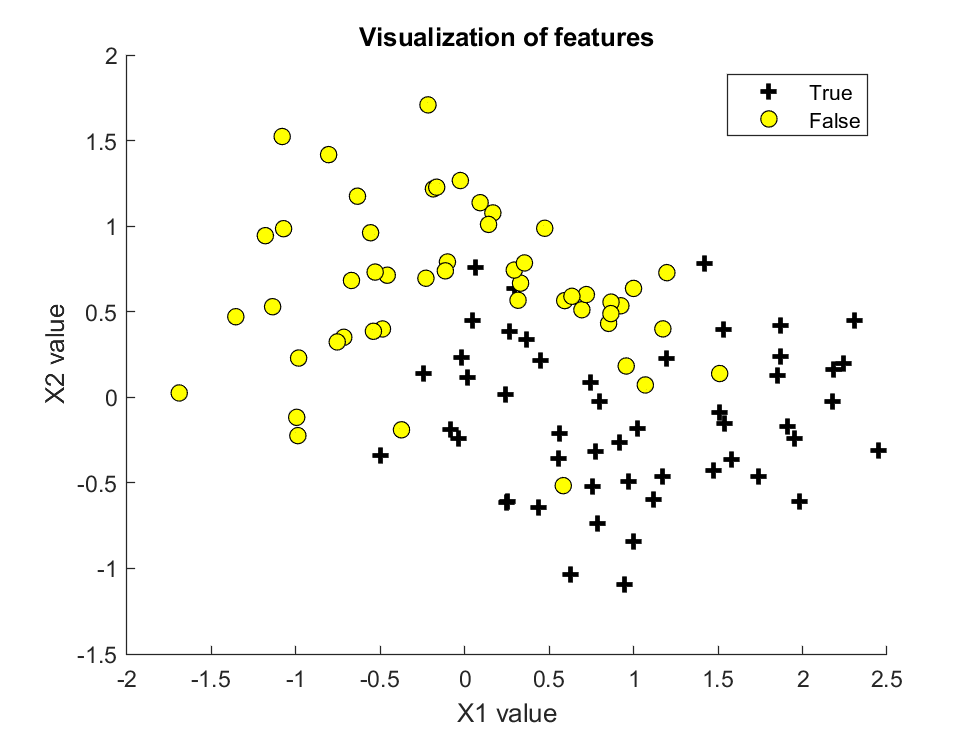

% Visualize data points
plotData(X, y, 'X1 value', 'X2 value');

### Learning parameters

In the following sections, we try to find a theta at minimal costs. Therefore we have to initialize some parameters:

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

#### Check functionality of cost function

% Compute and display initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

%Print cost to screen
disp(['Cost at initial theta (zeros):' newline, ...
      '[' num2str(cost) ']' newline, ...
      'Gradient at initial theta (zeros):' newline, ...
      '[' num2str(grad(:).') ']']);

Cost at initial theta (zeros):
[0.69315]
Gradient at initial theta (zeros):
[0    -0.25793     0.19052]


#### Split into train and cross-validation dataset

For the further processing, we split out dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X, y);

#### Learning theta using *fminunc*

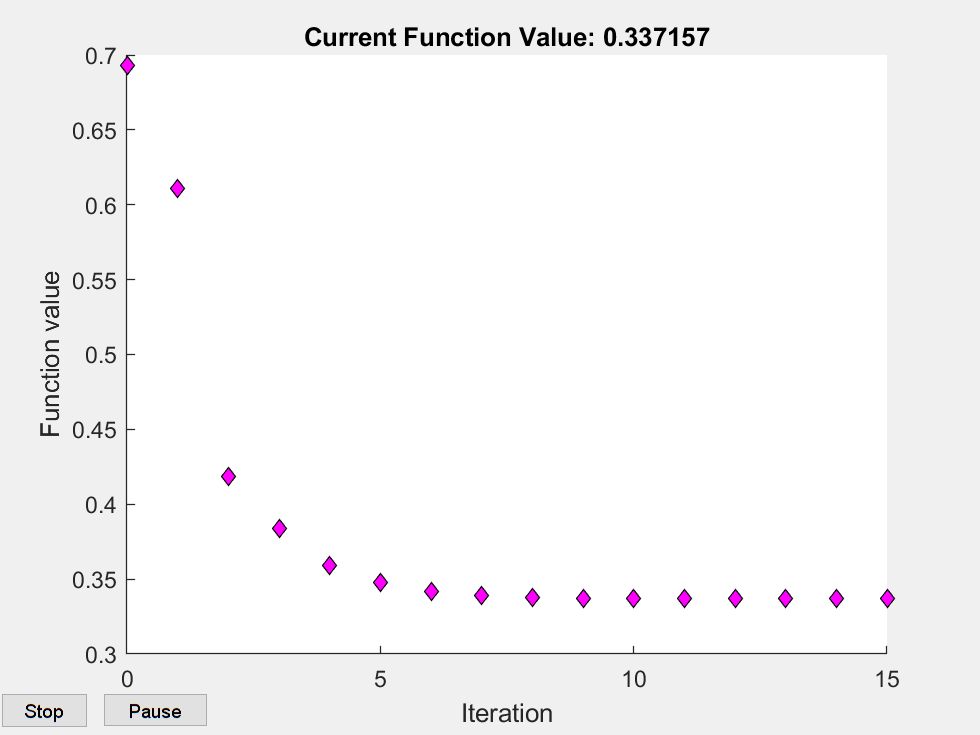

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400, 'PlotFcns', @optimplotfval, 'Display', 'off');

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta_fminunc, cost_fminunc] = ...
	fminunc(@(t)(costFunction(t, X_train, y_train)), initial_theta, options);

% Print theta to screen
disp(['Cost at theta found by fminunc:' newline, ...
      '[' num2str(cost_fminunc) ']' newline, ...
      'Theta:' newline, ...
      '[' num2str(theta_fminunc(:).') ']']);

Cost at theta found by fminunc:
[0.33716]
Theta:
[0.37557      1.3412     -4.2135]


To verify the behaviour of our model we can plot the linear decision boundary:

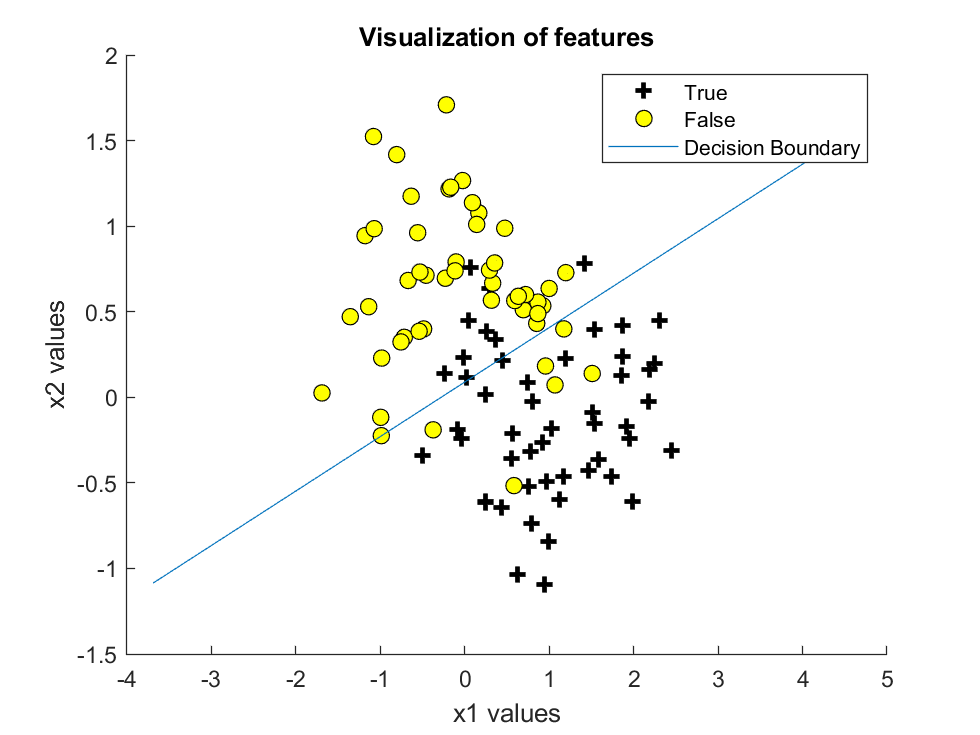

% Plot Boundary
plotDecisionBoundary(theta_fminunc, X, y, 'x1 values', 'x2 values');

By plotting a learning curve, we can easily define further steps for our model. Since the values differ from model to model, the axes are not scaled more precisely. As we do not use regularization, we can set lambda to 0.

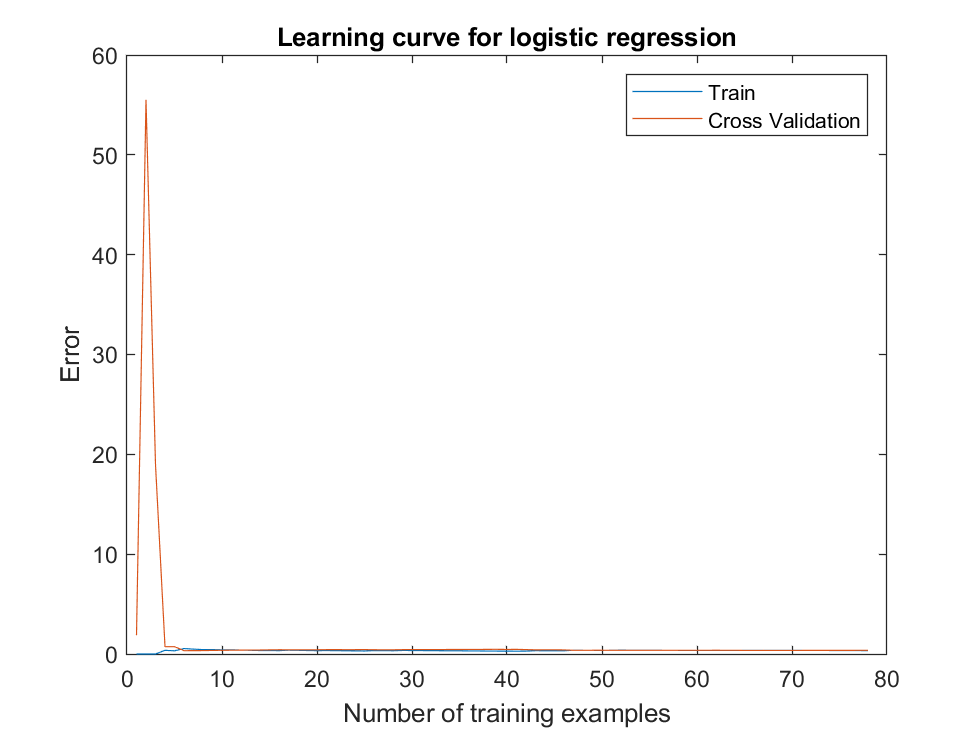

% Disable regularization
lambda = 0;

% Plot learning curve
stepsize = 1;
plotLearningCurve(X_train, y_train, X_val, y_val, lambda, stepsize);

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

#### Confusion Matrix

% Compute confusion matrix on our development set
cm = confusionmatrix(theta_fminunc, X_val, y_val);

disp(['Cross-validation Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']']);

Cross-validation Confusion Matrix:
[10   1   1   8]


#### Accuracy

% Compute accuracy on our development set
a = accuracy(theta_fminunc, X_val, y_val);

fprintf('Cross-validation Accuracy (percentage): %f\n', a);

Cross-validation Accuracy (percentage): 90.000000


#### Precision

% Compute precision on our development set
p = precision(theta_fminunc, X_val, y_val);

fprintf('Cross-validation Precision: %f\n', p);

Cross-validation Precision: 0.909091


#### Recall

% Compute recall on our development set
r = recall(theta_fminunc, X_val, y_val);

fprintf('Cross-validation Recall: %f\n', r);

Cross-validation Recall: 0.909091


#### F score

% Compute F score on our development set
f = fscore(theta_fminunc, X_val, y_val);

fprintf('Cross-validation F score: %f\n', f);

Cross-validation F score: 0.909091


### Add regularization to the model

To potentially improve our model, we add polynomial features to our data matrix. Later in this section we will use a regularization parameter lambda to prevent overfitting.

% Initialize variables
X = table2array(dev_data(:, [{'X1'}, {'X2'}]) );
y = table2array(dev_data(:, {'y'}) );

% Add features
X_poly = mapFeature(X(:,1), X(:,2), 6);

Before we can optimize theta, however, we have to normalize the individual features. To get a first impression of using regularization we choose lambda = 1. This value we can still vary at a later time.

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X_poly(:,2:end));
X_norm = [ones(m, 1), X_norm];

% Set regularization parameter lambda to 1
lambda = 1;

% Initialize fitting parameters
initial_theta = zeros(size(X_norm, 2), 1);

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X_norm, y, lambda);

disp(['Cost at initial theta (zeros):' newline, ...
      '[' num2str(cost) ']' newline, ...
      ['Gradient at initial' ...
      ' theta (zeros):'] newline, ...
      '[' num2str(grad(:).') ']']);

Cost at initial theta (zeros):
[0.69315]
Gradient at initial theta (zeros):
[0    -0.27501     0.32367    -0.17296    0.025178      0.1911    -0.22582     0.15393    -0.17385     0.22025    -0.17375    0.007973   0.0077203   -0.060065     0.14316     -0.1825    0.041896    -0.18907     0.14428    -0.12334     0.14463    -0.15579 -0.00036356   -0.098682   -0.046852    0.069107   -0.081213     0.11042]


For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_poly, y);

This time, we use fminc to learn our optimal theta:

% Set initial params
initial_theta = zeros(size(X_train, 2), 1); 

% Create "short hand" for the cost function to be minimized
costFunction = @(t) costFunctionReg(t, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument
options = optimset('GradObj', 'on', 'MaxIter', 800, 'PlotFcns', @optimplotfval);

% Minimize using fminc
theta_fminc = fmincg(costFunction, initial_theta, options);

To verify the behaviour we can plot the found decision boundary:

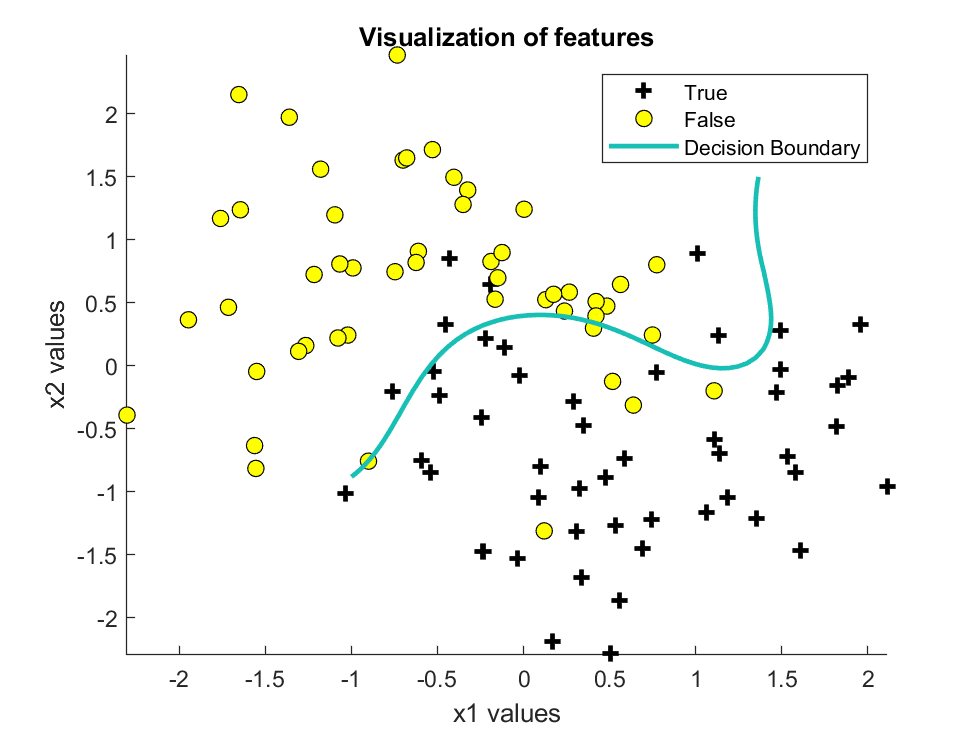

% Plot Boundary
degree = 6;
plotDecisionBoundary(theta_fminc, X_norm, y, 'x1 values', 'x2 values', degree);

In order to judge the quality of the model, we can again calculate some metrics:

% Compute accuracy on our development set
cm = confusionmatrix(theta_fminc, X_val, y_val);

% Compute accuracy on our development set
a = accuracy(theta_fminc, X_val, y_val);

% Compute precision on our development set
p = precision(theta_fminc, X_val, y_val);

% Compute recall on our development set
r = recall(theta_fminc, X_val, y_val);

% Compute F score on our development set
f = fscore(theta_fminc, X_val, y_val);

disp(['Cross-validation Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Cross-validation Accuracy (%): ', num2str(a) newline, ...
      'Cross-validation Precision: ', num2str(p) newline, ...
      'Cross-validation Recall: ', num2str(r) newline, ...
      'Cross-validation F score: ', num2str(f)]);

Cross-validation Confusion Matrix:
[9  2  1  8]
Cross-validation Accuracy (%): 85
Cross-validation Precision: 0.9
Cross-validation Recall: 0.81818
Cross-validation F score: 0.85714


clear ; close all; clc 

## **Model 1: Using non regluarized features***** living area***** / *****price*** 

For a first and easy to understand model the features *living area* and *price* are used.

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

As we will split the data later in a training and a cross validation part, we have to randomly order the data, The data will then be classified into two groups "House" or "Apartment or Other". For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'number_of_buildings_in_hectare'}, {'population_in_hectare'}])));
% Binarize categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

### Visualize data

The loaded data is visualized in a next step to unterstand the problem we are working with.

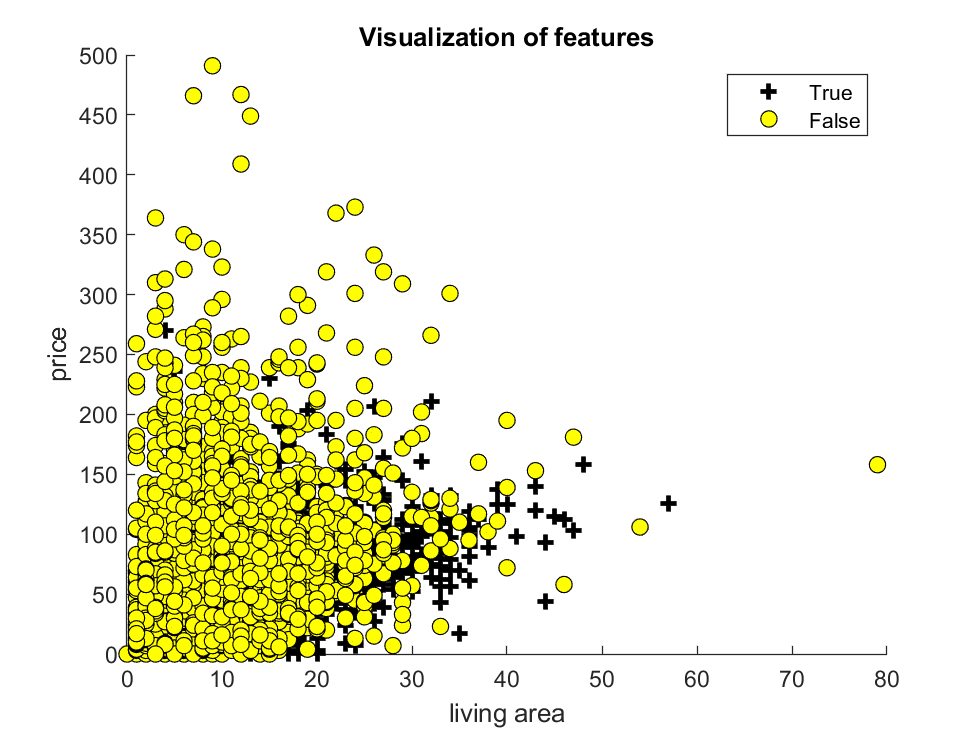

% Visualize data points
plotData(X, y, 'living area', 'price');

### Learning parameters

In the following sections, we try to find a theta at minimal costs. Therefore we have to initialize some parameters:

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

#### Normalize features

Before we can optimize our theta, we first have to bring our features on a similar scale using feature normalization:

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X(:,2:end));
X_norm = [ones(m, 1), X_norm];

#### Split into train and cross-validation dataset

For the further processing, we split out dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

#### Learning theta using *fminunc*

Using fminunc, the development of costs can be displayed via the number of iterations. This can be seen in the plot below.

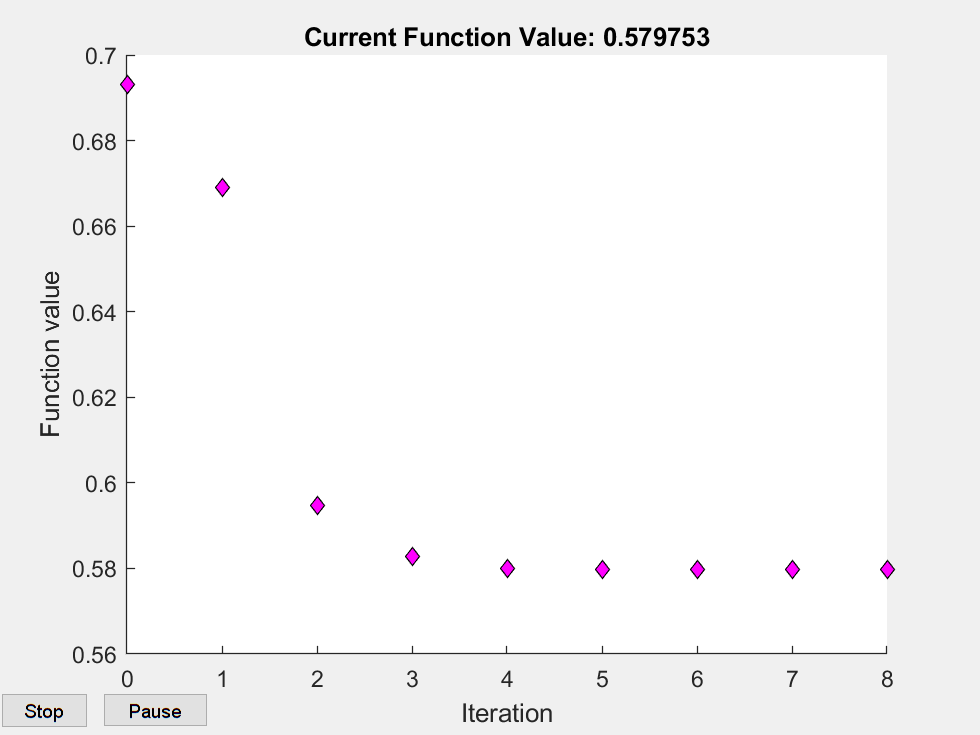

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400, 'PlotFcns', @optimplotfval, 'Display', 'off');

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta_fminunc, cost_fminunc] = ...
	fminunc(@(t)(costFunction(t, X_train, y_train)), initial_theta, options);

% Print theta to screen
disp(['Cost at theta found by fminunc:' newline, ...
      '[' num2str(cost_fminunc) ']' newline, ...
      'Theta:' newline, ...
      '[' num2str(theta_fminunc(:).') ']']);

Cost at theta found by fminunc:
[0.57975]
Theta:
[-0.01888        1.13     -1.4196]


To verify the behaviour we can plot the found decision boundary:

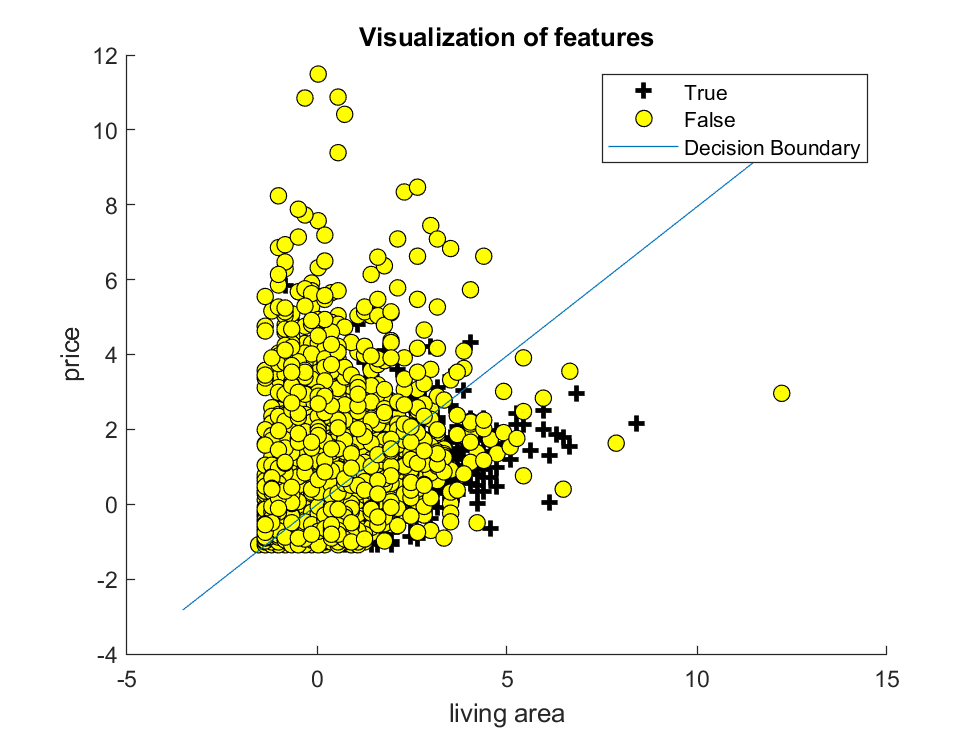

% Plot Boundary
plotDecisionBoundary(theta_fminunc, X_norm, y, 'living area', 'price');

### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

% Compute accuracy on our development set
cm = confusionmatrix(theta_fminunc, X_val, y_val);

% Compute accuracy on our development set
a = accuracy(theta_fminunc, X_val, y_val);

% Compute precision on our development set
p = precision(theta_fminunc, X_val, y_val);

% Compute recall on our development set
r = recall(theta_fminunc, X_val, y_val);

% Compute F score on our development set
f = fscore(theta_fminunc, X_val, y_val);

disp(['Cross-validation Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Cross-validation Accuracy (%): ', num2str(a) newline, ...
      'Cross-validation Precision: ', num2str(p) newline, ...
      'Cross-validation Recall: ', num2str(r) newline, ...
      'Cross-validation F score: ', num2str(f)]);

Cross-validation Confusion Matrix:
[1487   345   619  1047]
Cross-validation Accuracy (%): 72.4414
Cross-validation Precision: 0.70608
Cross-validation Recall: 0.81168
Cross-validation F score: 0.75521


###  Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Initialize variables
X = table2array(test_data_ordered(:, [{'living_area'}, {'price'}]) );
m = size(X,1);
X = [ones(m, 1) X];

% Binarize categorical value object_type
y_raw = table2array(test_data_ordered(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X(:,2:end));
X = [ones(m, 1), X_norm];

In order to judge the quality of the model, we can again calculate some metrics:

% Compute accuracy on our test set
cm = confusionmatrix(theta_fminunc, X, y);

% Compute accuracy on our test set
a = accuracy(theta_fminunc, X, y);

% Compute precision on our test set
p = precision(theta_fminunc, X, y);

% Compute recall on our test set
r = recall(theta_fminunc, X, y);

% Compute F score on our test set
f = fscore(theta_fminunc, X, y);

disp(['Test Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Test Accuracy (%): ', num2str(a) newline, ...
      'Test Precision: ', num2str(p) newline, ...
      'Test Recall: ', num2str(r) newline, ...
      'Text F score: ', num2str(f)]);

Test Confusion Matrix:
[1489  1149  1451   991]
Test Accuracy (%): 48.8189
Test Precision: 0.50646
Test Recall: 0.56444
Text F score: 0.53388


By plotting a learning curve, we can easily define further steps for our model. As we do not use regularization, we can set lambda to 0. In the plot it can be seen (in most executions) that we tend to underfit the data. In the next step we will add more features.

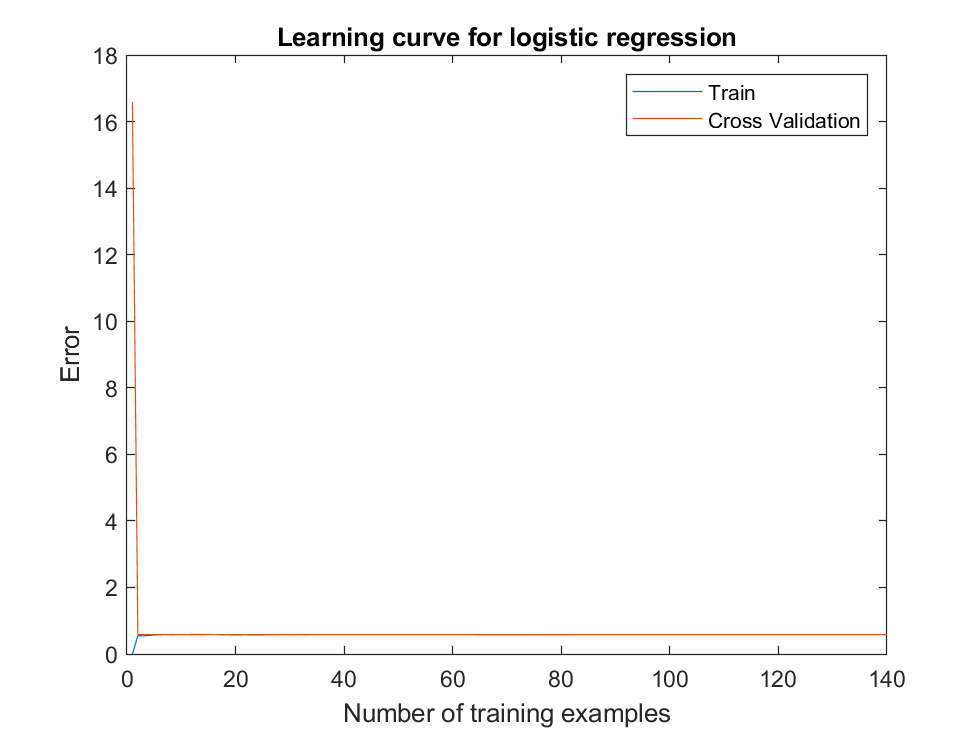

% Disable regularization
lambda = 0;

% Plot learning curve
stepsize = 100;
plotLearningCurve(X_train, y_train, X_val, y_val, lambda, stepsize);

clear ; close all; clc 

## Model 2: Adding further features to the model

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

 As we will split the data later in a training and a cross validation part, we have to randomly order the data, The data will then be classified into two groups "House" or "Apartment or Other". For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));
                           
% Binarize categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

### Learning parameters

In the following sections, we try to find a theta at minimal costs. Therefore we have to initialize some parameters:

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

Before we can optimize our theta, we first have to bring our features on a similar scale using feature normalization:

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X(:,2:end));
X_norm = [ones(m, 1), X_norm];

#### Split into train and cross-validation dataset

For the further processing, we split out dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

#### Learning theta using *fminunc*

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400, 'PlotFcns', @optimplotfval, 'Display', 'off');

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta_fminunc, cost_fminunc] = ...
	fminunc(@(t)(costFunction(t, X_train, y_train)), initial_theta, options);
% Print theta to screen
disp(['Cost at theta found by fminunc:' newline, ...
      '[' num2str(cost_fminunc) ']' newline, ...
      'Theta:' newline, ...
      '[' num2str(theta_fminunc(:).') ']']);

Cost at theta found by fminunc:
[0.41525]
Theta:
[0.044351      0.8206   0.0058805    -0.47374     0.15813    0.050469     0.86077   -0.002587    -0.23676     0.07555      1.3192     -1.6978     0.13517   -0.075646   -0.038389    -0.30124    0.016049]


### Statistics for the evaluation of the model

Various metrics are used to assess the quality of the model.

% Compute accuracy on our development set
cm = confusionmatrix(theta_fminunc, X_val, y_val);

% Compute accuracy on our development set
a = accuracy(theta_fminunc, X_val, y_val);

% Compute precision on our development set
p = precision(theta_fminunc, X_val, y_val);

% Compute recall on our development set
r = recall(theta_fminunc, X_val, y_val);

% Compute F score on our development set
f = fscore(theta_fminunc, X_val, y_val);

disp(['Cross-validation Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Cross-validation Accuracy (%): ', num2str(a) newline, ...
      'Cross-validation Precision: ', num2str(p) newline, ...
      'Cross-validation Recall: ', num2str(r) newline, ...
      'Cross-validation F score: ', num2str(f)]);

Cross-validation Confusion Matrix:
[1537   259   332  1370]
Cross-validation Accuracy (%): 83.1046
Cross-validation Precision: 0.82236
Cross-validation Recall: 0.85579
Cross-validation F score: 0.83874


### Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Initialize variables
X = double(table2array(test_data_ordered(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));
m = size(X,1);
X = [ones(m, 1) X];

% Binarize categorical value object_type
y_raw = table2array(test_data_ordered(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X(:,2:end)); % FIXME Temporarily remove first column
X = [ones(m, 1), X_norm];

In order to judge the quality of the model, we can again calculate some metrics:

% Compute accuracy on our test set
cm = confusionmatrix(theta_fminunc, X, y);

% Compute accuracy on our test set
a = accuracy(theta_fminunc, X, y);

% Compute precision on our test set
p = precision(theta_fminunc, X, y);

% Compute recall on our test set
r = recall(theta_fminunc, X, y);

% Compute F score on our test set
f = fscore(theta_fminunc, X, y);

disp(['Test Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Test Accuracy (%): ', num2str(a) newline, ...
      'Test Precision: ', num2str(p) newline, ...
      'Test Recall: ', num2str(r) newline, ...
      'Text F score: ', num2str(f)]);

Test Confusion Matrix:
[2286   352   499  1943]
Test Accuracy (%): 83.248
Test Precision: 0.82083
Test Recall: 0.86657
Text F score: 0.84308


By plotting a learning curve, we can still recognize, that we underfit our data. We therefore map higher polynomial features to our model to get a tighter fit.

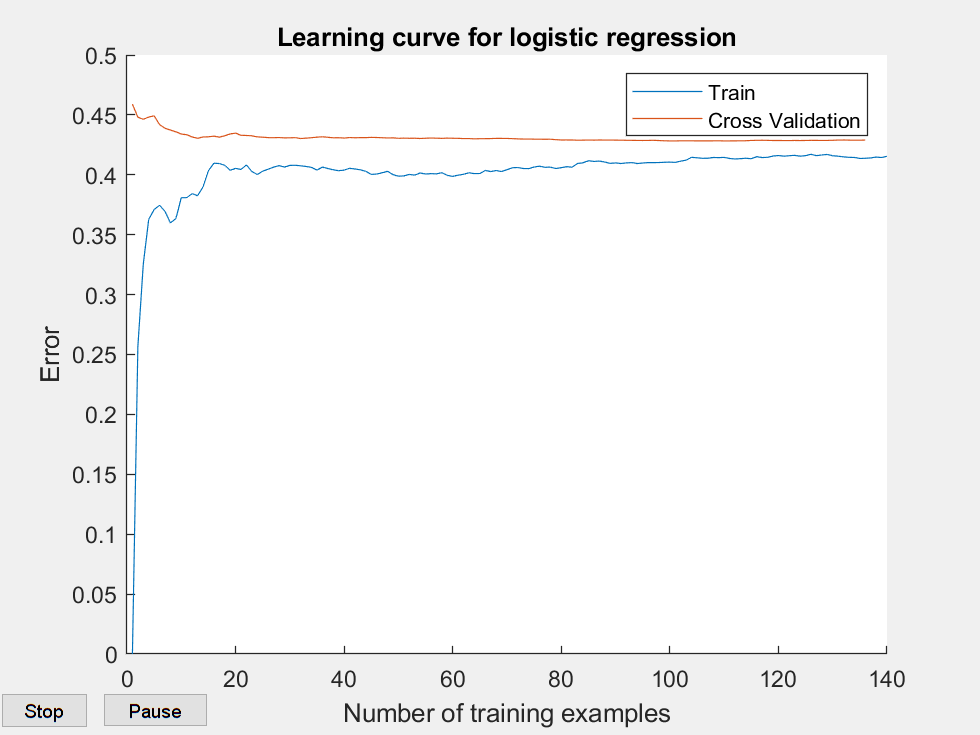

% Disable regularization
lambda = 0;

% Plot learning curve
stepsize = 100;
plotLearningCurve(X_train, y_train, X_val, y_val, lambda, stepsize);

clear ; close all; clc 

## Model 3: Adding higher polynomial features and regularization

To potentially improve our model, we add polynomial features to our data matrix. Later in this section we will use a regularization parameter lambda to prevent overfitting.

### Load traing data

The data used for the training phase will be read from a given file *house_train*`.csv`. The description of the data and their origin is not part of this assignment. Below the first five rows will be displayed:

% Load tain data
train_data_ordered = importHouseData('house_train.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name     price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ______________

As we will split the data later in a training and a cross validation part, we have to randomly order the data, The data will then be classified into two groups "House" or "Apartment or Other". For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Randomly order data
train_data = train_data_ordered(randperm(size(train_data_ordered,1)),:);

% Initialize variables
X = double(table2array(train_data(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));
                           
% Binarize categorical value object_type
y_raw = table2array(train_data(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

% Add features
m = size(X,1);
ncols = size(X,2);
X_poly = [];
degree = 6;

for k = 1:ncols
    X_poly_cur = polyFeatures(X(:, k), degree);
    X_poly = [X_poly X_poly_cur ]; 
end

X_poly = [ones(m, 1) X_poly];

Before we can optimize theta, however, we have to normalize the individual features. To prevent from overfitting, we choose lambda = 2.

% Normalize features
m = size(X, 1);
[X_norm, mu, sigma] = featureNormalize(X_poly(:,2:end));
X_norm = [ones(m, 1), X_norm];

% Set regularization parameter lambda to 2
lambda = 2;

% Initialize fitting parameters
initial_theta = zeros(size(X_norm, 2), 1);

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X_norm, y, lambda);

disp(['Cost at initial theta (zeros):' newline, ...
      '[' num2str(cost) ']' newline, ...
      ['Gradient at initial' ...
      ' theta (zeros):'] newline, ...
      '[' num2str(grad(:).') ']']);

Cost at initial theta (zeros):
[0.69315]
Gradient at initial theta (zeros):
[-0.019383    -0.16162   -0.065667    -0.02842   -0.017614   -0.013614   -0.011648    -0.10959   -0.076664   -0.051105   -0.035508   -0.026564   -0.021268     0.08658     0.10033      0.1068     0.11145      0.1153     0.11865   -0.068267   -0.068078   -0.067884   -0.067685   -0.067481   -0.067272    0.029786    0.032931    0.035844    0.038489    0.040844    0.042898    -0.20912   -0.094577   -0.022556  -0.0087498  -0.0065725  -0.0062538   0.0073454   0.0073454   0.0073454   0.0073454   0.0073454   0.0073454      0.0598     0.07365    0.068826    0.057074    0.044861    0.034896    0.046548     0.06459    0.062805    0.053543    0.043597    0.035196   -0.099219   -0.075326   -0.040217   -0.015047  -0.0036669  0.00068678     0.17371     0.12478    0.069589    0.037961    0.023227     0.01617    0.069593    0.016741   0.0059547   0.0043469   0.0040288   0.0039539   0.0064345   0.0066095   0.0067573   0.0067304  

For the further processing, we split our dataset into a training and a cross-validation part:

[X_val, y_val, X_train, y_train] = splitData(X_norm, y);

This time, we use fminc to learn our optimal theta:

% Set initial params
initial_theta = zeros(size(X_train, 2), 1); 

% Create "short hand" for the cost function to be minimized
costFunction = @(t) costFunctionReg(t, X_train, y_train, lambda);

% Now, costFunction is a function that takes in only one argument
options = optimset('GradObj', 'on', 'MaxIter', 800, 'PlotFcns', @optimplotfval);

% Minimize using fminc
theta_fminc = fmincg(costFunction, initial_theta, options);

In order to judge the quality of the model, we can again calculate some metrics:

% Compute accuracy on our development set
cm = confusionmatrix(theta_fminc, X_val, y_val);

% Compute accuracy on our development set
a = accuracy(theta_fminc, X_val, y_val);

% Compute precision on our development set
p = precision(theta_fminc, X_val, y_val);

% Compute recall on our development set
r = recall(theta_fminc, X_val, y_val);

% Compute F score on our development set
f = fscore(theta_fminc, X_val, y_val);

disp(['Cross-validation Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Cross-validation Accuracy (%): ', num2str(a) newline, ...
      'Cross-validation Precision: ', num2str(p) newline, ...
      'Cross-validation Recall: ', num2str(r) newline, ...
      'Cross-validation F score: ', num2str(f)]);

Cross-validation Confusion Matrix:
[1618   223   254  1403]
Cross-validation Accuracy (%): 86.3636
Cross-validation Precision: 0.86432
Cross-validation Recall: 0.87887
Cross-validation F score: 0.87153


### Apply model to test data

The optimized model can now be applied to the test dataset. The data is located in the file *house_test.csv*.

% Load test data
test_data_ordered = importHouseData('house_test.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long          municipality_name    zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    _______________

For an easier processing of the data an additional column is introduced. This column contains the value 1, if it is a house dataset. Otherwise the column contains the value 0.

% Initialize variables
X = double(table2array(test_data_ordered(:, [{'living_area'},
    {'price'},
    {'build_year'},
    {'lat'},
    {'long'},
    {'num_rooms'},
    {'water_percentage_1000'},
    {'travel_time_private_transport'},
    {'travel_time_public_transport'},
    {'number_of_buildings_in_hectare'},
    {'number_of_apartments_in_hectare'},
    {'number_of_workplaces_in_hectare'},
    {'number_of_workplaces_sector_1_in_hectare'},
    {'number_of_workplaces_sector_2_in_hectare'},
    {'number_of_workplaces_sector_3_in_hectare'},
    {'population_in_hectare'}])));

% Add features
m = size(X,1);
ncols = size(X,2);
X_poly = [];
degree = 6;
for k = 1:ncols
    X_poly_cur = polyFeatures(X(:, k), degree);
    X_poly = [X_poly X_poly_cur ]; 
end
X_poly = [ones(m, 1) X_poly];

% Binarize categorical value object_type
y_raw = table2array(test_data_ordered(:, {'object_type_name'}) );
% Binarize categorical value object_type
y = binarizeData(y_raw);

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X_poly(:,2:end)); % FIXME Temporarily remove first column
X = [ones(m, 1), X_norm];

In order to judge the quality of the model, we can again calculate some metrics:

% Compute accuracy on our test set
cm = confusionmatrix(theta_fminc, X, y);

% Compute accuracy on our test set
a = accuracy(theta_fminc, X, y);

% Compute precision on our test set
p = precision(theta_fminc, X, y);

% Compute recall on our test set
r = recall(theta_fminc, X, y);

% Compute F score on our test set
f = fscore(theta_fminc, X, y);

disp(['Test Confusion Matrix:' newline, ...
      '[' num2str(cm(:).') ']' newline, ...
      'Test Accuracy (%): ', num2str(a) newline, ...
      'Test Precision: ', num2str(p) newline, ...
      'Test Recall: ', num2str(r) newline, ...
      'Text F score: ', num2str(f)]);

Test Confusion Matrix:
[2314   324   434  2008]
Test Accuracy (%): 85.0787
Test Precision: 0.84207
Test Recall: 0.87718
Text F score: 0.85926
